# **Velocity Profile Generation Using Trapezoidal Profile**

The script generates the reference velocity based on the following method: 

**Radius of curvature and friction based trapezoidal profile: **The radius of curvature feature is an addition to the trapezoidal profile. It restricts the maximum velocity of the vehicle at curved roads. This feature is not inclusive of the trapezoidal function as robots would always stop at intersections and accelerate linearly after changing the direction. *Use this function with tracks with multiple curves.*

#### How to use the script?

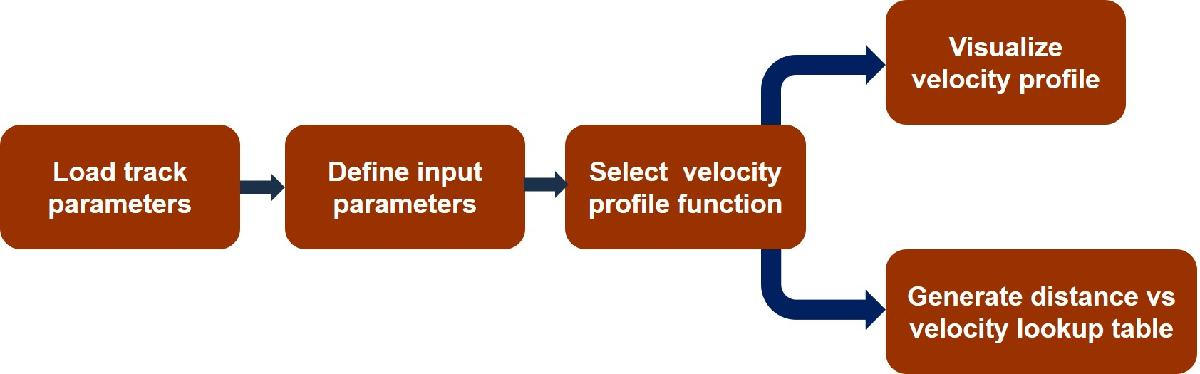

#### Input Parameters

% load track parameters, all units are in mm
load SysTraj.mat xRef2s yRef2s totalDistance
% define waypoints (mm)
wayp = [xRef2s yRef2s];

% maximum velocity (m/s)
Ts = 1 ;
vmax = abs(diff(wayp))/Ts*1.5;
vmax(vmax==0) = Ts*1.5;
% vmax(vmax<Ts*1.5) = Ts*1.5;
% time travelled between 2 waypoints (s)

#### Select Velocity Profile Function, tested with trapezoidal velocity profile

% Select the function to generate the velocity profile
% trapezoidal velocity profile
[poscmp,poslt,velmap,vel,ts] = radtrap(wayp',vmax',Ts);
% polynomial velocity profile
% [poscmp,poslt,velmap,vel] = radfricpoly(wayp'/1e3,totalDistance/1e3,v_avg,maxvel,fric,nst);
poscmp = 1e3*poscmp;
poslt = 1e3*poslt;

#### **Distance and Velocity Calculation for Simulink Lookup Table**

xRef = wayp(:,1);
yRef = -wayp(:,2);
X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y direction

% extract the vehicle x and y values
poslt_xy = [poslt(1,:); poslt(2,:)]';
distancematrix = squareform(pdist(poslt_xy));
distancesteps = zeros(length(poslt_xy)-1,1);
for i = 2:length(poslt_xy)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end

% distance at each time step
dislt = cumsum([0; distancesteps]');% + sqrt((X_o).^2+(Y_o).^2);
distancecovered = dislt(end);
velt_res = vel(3,:); % vehicle resultant velocity (m/s)

% The vehicle starts with a zero velocity. 
% Hence, to define an initial non-zero velocity first 6 rows are replaced
% by the value in the 7th row. Please feel free to comment out this if you want
% to start the vehicle with zero velocity
%
% velt_res(1:6) = velt_res(7); 

#### Plots

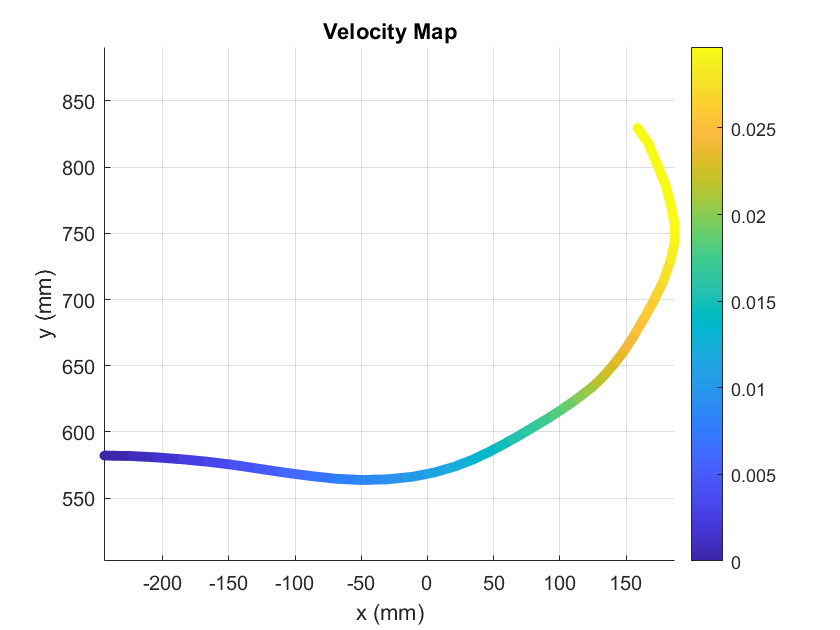

x = poscmp(1,:);
y = poscmp(2,:);
sz = 25;
c = velmap(3,:);
figure(1)
scatter(x,y,sz,c,'filled')
colorbar
grid on, axis equal
xlabel('x (mm)')
ylabel('y (mm)')
title('Velocity Map')

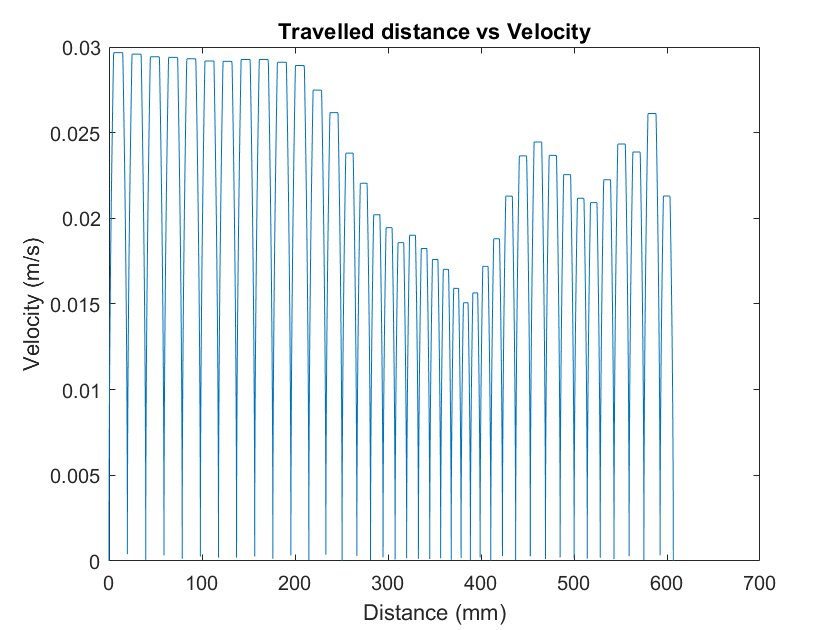

figure(2)
% for trapezoidal velocity profile
% subplot(2,1,1)
plot(dislt, vel(3,:))
xlabel('Distance (mm)')
ylabel('Velocity (m/s)')
title('Travelled distance vs Velocity')

% subplot(2,1,2)
% plot(dislt, velt_res)
% xlabel('Distance (mm)')
% ylabel('Velocity (m/s)')
% title('Travelled distance vs Velocity (finite initial velocity)')

close all